## Mightex TCE-1304-U

This notebook tests the Matlab interface to the `mightex1304` library. It also assesses the noise level of the CCD sensor.

clear variables;

## Initialization

The interface is object-based and wraps the underlying C library using Matalb `loadlibrary` family of functions.

When you create an instance of the `mightex` class, it loads the C library, searches for the connected device and opens a connection to it. With no arguments, it searches for the library under the relative paths as if this file were installed under the `interfaces/matlab` folder within the package directory. If the locations are different, you have to specify  the path to the library and to the header file:

m=mightex( ...
  "../products_host/lib/libmightex.dylib", ...
  "../products_host/include/mightex1304.h" ...
)

Connected to camera 13-201114-001


m =   mightex with properties:

         Library: "../products_host/lib/libmightex.dylib"
          Header: "../products_host/include/mightex1304.h"
         NPixels: 3648
          Serial: '13-201114-001'
    ExposureTime: 1
           Frame: [1×1 lib.pointer]
        RawFrame: [1×1 lib.pointer]
          IsOpen: 1
             Mtx: [1×1 lib.pointer]


Pay attention that, under different architectures, path and file extension of the dynamic library are different.

Note that the output of the command provides the serial number of the attached device, which shall correspond to that printed on the back of the device.

**Warning: never create a new object before closing and deleting the previous one. Matlab might crash.**

## Get info on the device and adjust its settings

Information on the device and on the library are available. 

The underlying library version can be read with a class method:

mightex.swVersion

ans = 'Mightex1304 v.0.2.0-10-g59fbd65§ for x86_64-apple-darwin20.5.0, Release build.'

Number of pixels, exposure time and serial number are available as read only values of the `m` object:

m.NPixels

ans = 3648

m.Serial

ans = '13-201114-001'

m.ExposureTime

ans = 1

The exposure time can be set drom a minimum of 0.1 ms in steps of 0.1 ms: to set it to 10 ms do:

m.setExposureTime(10)

## Reading frames, and across-the-sensor noise assessment

Frames (i.e. 1-D images) are read with the `readFrame` method. That method returns up to two arguments: the first is the *filtered* frame, the second is the *raw* frame. The filter that is automatically applied is the default for the mightex library: subtracts from each pixel value the average of the 13 shielded pixels. In this case we are reading a frame when the camera sensor is protected by the metal cap: it shall see no light, so the difference between the average of the 13 shielded pixels and the average of normal pixels shall be close to zero.

[frame, rawFrame] = m.readFrame();
mean(frame)

ans = 27.5192

mean(rawFrame)

ans = 1.6421e+03

m.darkMean

ans = 1627

[hypot, pval] = ttest(double(rawFrame), m.darkMean);
pval

pval = 7.2154e-77

The very low p-value tells that the difference between the raw frame values average and the mean of the dark pixels is in fact negligible.

Of course, the mean of  the filtered `frame` is not zero, for `frame` is down-saturated to zero.

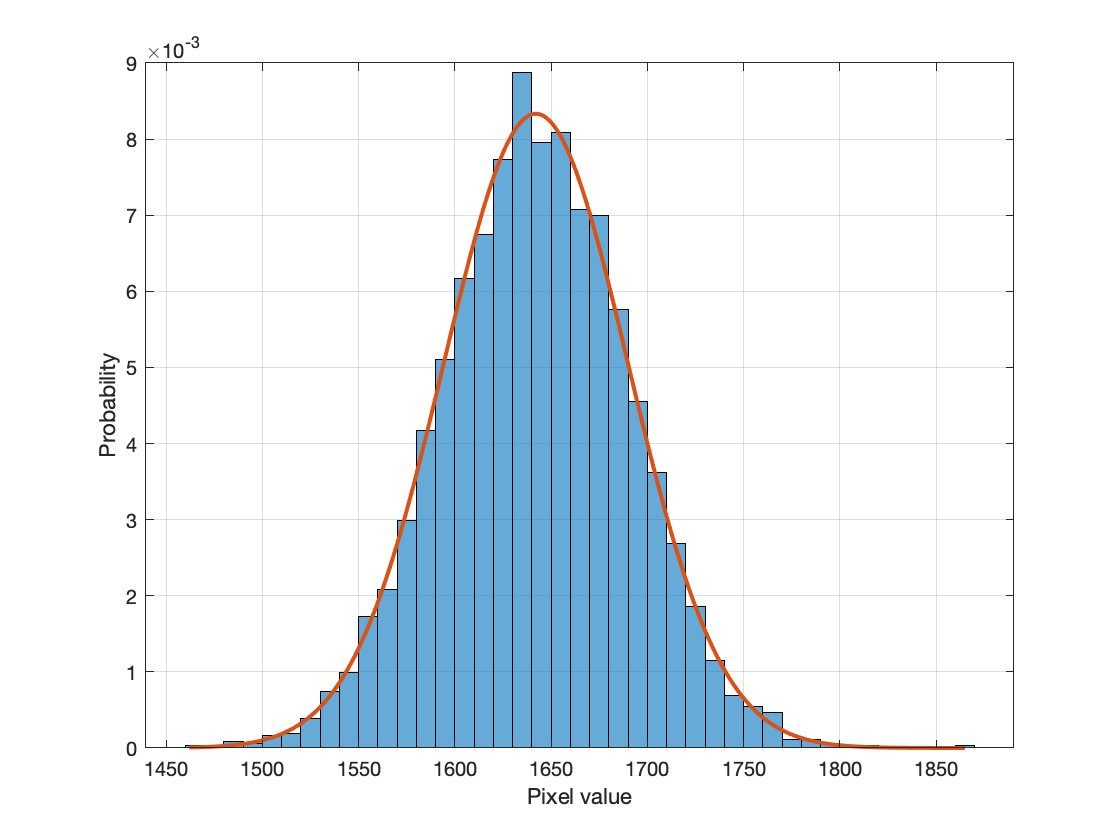

x = double(min(rawFrame):1:max(rawFrame));
fm = mean(rawFrame);
fs = std(double(rawFrame));
histogram(rawFrame, "Normalization","pdf")
hold on;
plot(x, pdf("Normal", x, fm, fs), "LineWidth", 2);
xlabel("Pixel value");
ylabel("Probability");
grid();
hold off;

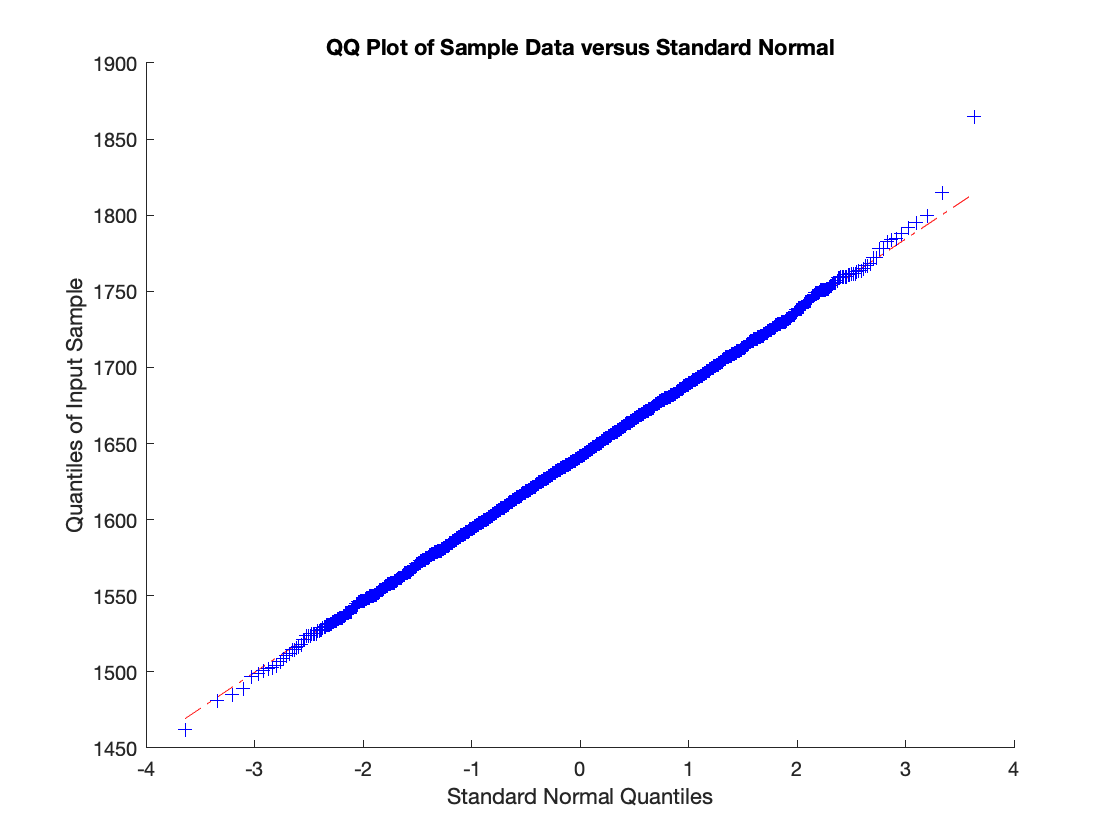

qqplot(double(rawFrame))

It is evident that the noise of non-illuminated pixels across the sensor is really normal.

## Time behavior

Now we see the *time*-related noise, by sampling many times the 1-D image at different times, and assessing the noise *at pixel level*. For doing that, we collect a number of subsequent frames equal to the number of pixels, building up a square matrix, let's call it `img`. Again, we are only using raw frames. We also create a row vector of timestamps (that overflow every $2^{16}$).

m.setExposureTime(0.1); % to spare some time...
img = zeros(m.NPixels);
times = zeros(1, m.NPixels);
st = tic;
for i = 1:m.NPixels
  [~,img(:,i)] = m.readFrame;
  times(i) = m.frameTimestamp;
end
dt = toc(st)
frameRate = m.NPixels / dt

**Note:** this loop takes about 28 s, so we break the section after that. Typically, the Matlab interface allows to read **about 130 frames/s**.

The pixel-by-pixel means and standard deviations are:

img_ppm = mean(img, 1);
img_pps = std(img, 0, 1);

while the frame-by-frame are:

img_ffm = mean(img, 2);
img_ffs = std(img, 0, 2);

Let's plot the results:

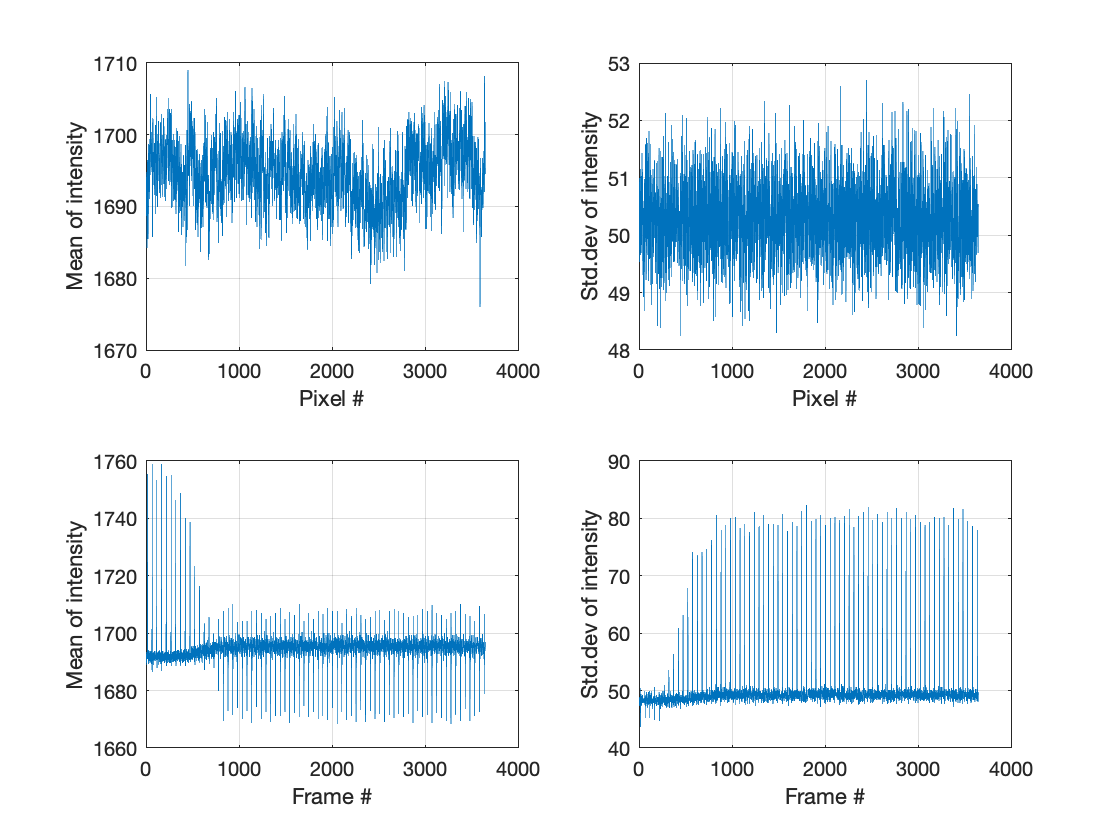

figure
yrngm = [0, 1000];
subplot(2,2,1)
plot(img_ppm)
xlabel("Pixel #");
ylabel("Mean of intensity")
grid()

subplot(2,2,2)
plot(img_pps)
xlabel("Pixel #");
ylabel("Std.dev of intensity")
grid()

subplot(2,2,3)
plot(img_ffm)
xlabel("Frame #");
ylabel("Mean of intensity")
grid()

subplot(2,2,4)
plot(img_ffs)
xlabel("Frame #");
ylabel("Std.dev of intensity")
grid()

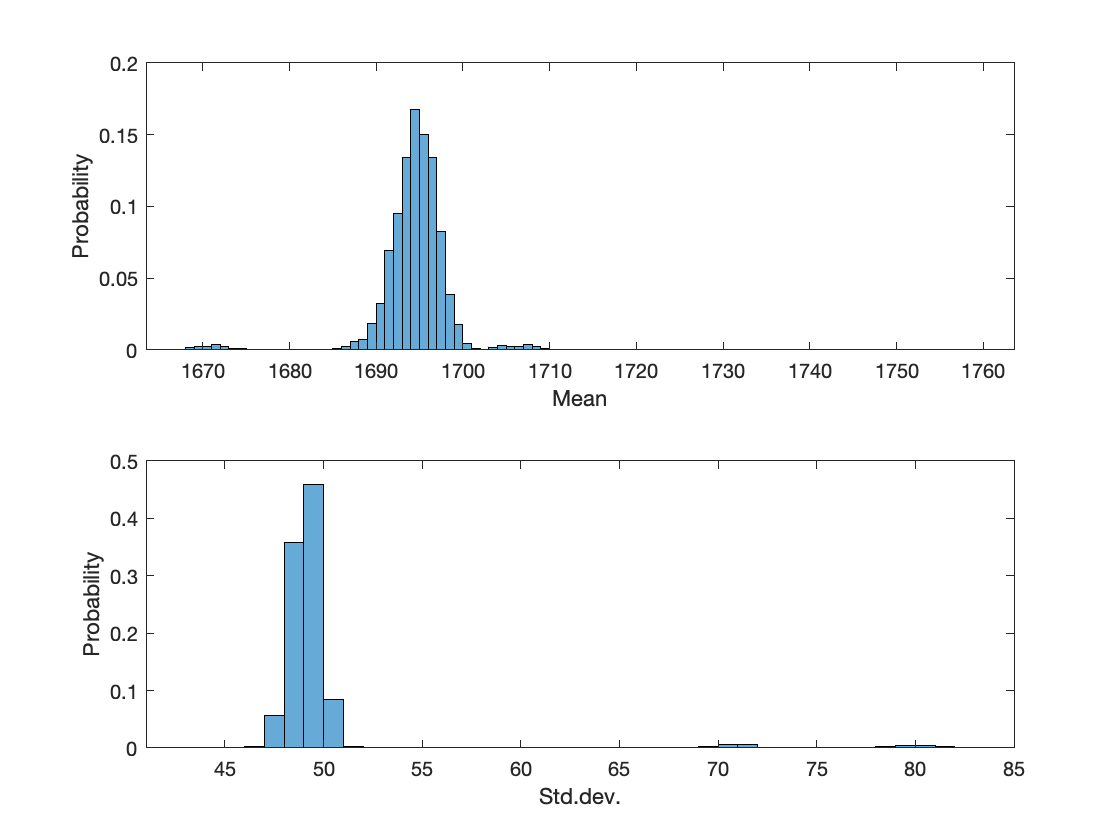

figure()
subplot(2,1,1)
histogram(img_ffm, "Normalization","pdf")
ylabel Probability
xlabel Mean
subplot(2,1,2)
histogram(img_ffs, "Normalization","pdf")
ylabel Probability
xlabel Std.dev.

figure();

It can be observed that the **reading of each pixel at dark** is rather comparable to the other pixels without significant deviation, the standard deviation falling in a range between 49 and 52 (ove 65536 values). By repeating the measurement, that apparent pattern in the pixel-by-pixel mean changes, meaning that it is a random noise source.

If we look at the rading of **the whole pixel line ad dark at different times**, it is evident that most of the readings have a mean of about 1695 and a standard deviation of about 49. Nonetheless, there is a periodic second population with much larger standard deviations (about 70 and 80). Additionally, the properties seem to stabilize after about 1000 frames. These observations repeats regularly at about 2.5 Hz, as it can be observed by the first peak on the FFT chart:

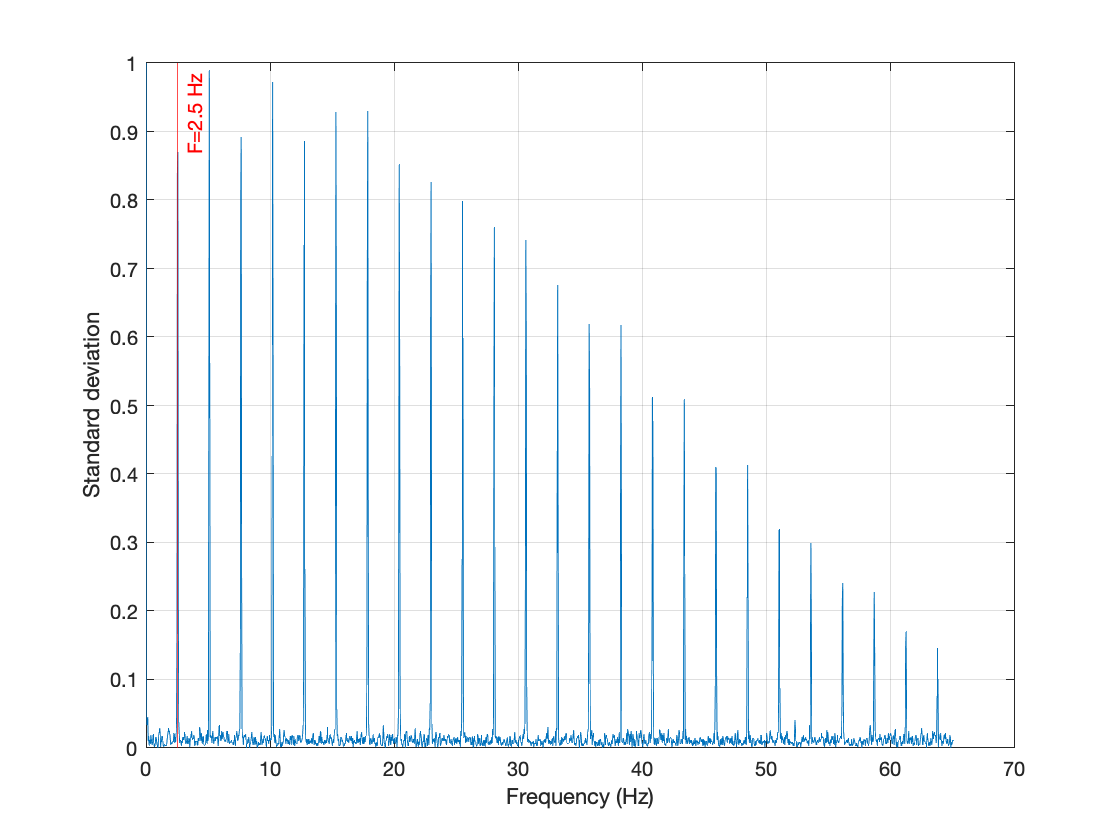

hann = sin(pi * (1:m.NPixels)/m.NPixels).^2; % Hann window
P2 = abs(fft(img_ffs .* hann')/m.NPixels);
P1 = P2(1:m.NPixels/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = frameRate*(0:(L/2))/L;
plot(f,P1)
xlabel("Frequency (Hz)")
ylabel("Standard deviation")
ylim([0 1])
xline(2.5, '-r', "F=2.5 Hz")
grid()

## Closing device

When we are done, we shall remember to close the device and unload the library. The device can be closed explicitly (method `close`), or implicitly by removing all associated variables:

clear variables

The library bust be then unloaded as per the comment above:

unloadlibrary libmightex